## Analysis of battery models using parameter sensitivity plots

clear
close all

### Variables

syms q z s FCC0 SOH R0 omega
Rd = sym('R_d');
taud = sym('tau_d');
omega  = sym('omega');
vars    = {     R0,       Rd, taud, SOH};
varvals = {0.565e-3, 0.896e-3,  224, 0.91};

### Electrochemistry model

G = (4.1-3.6)/(0.9-0.1)/(FCC0*SOH)/s+R0+Rd/sqrt(taud*s)*tanh(sqrt(taud*s))

$$G = R_{0}+\frac{R_{d}\,\tanh\left(\sqrt{s\,\tau_{d}}\right)}{\sqrt{s\,\tau_{d}}}+\frac{5}{8\,{\mathrm{FCC}}_{0}\,\mathrm{SOH}\,s}$$

G = subs(G,FCC0,65.6*3600);

Display sensitivity plot 

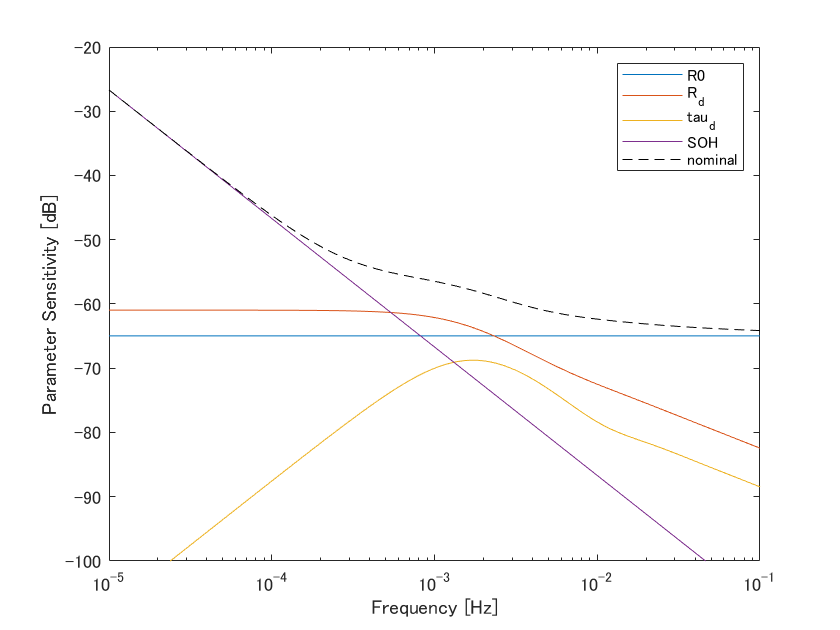

freq = logspace(-5,-1,100);
sensitibity_plot(G,freq,vars,varvals);
ylim([-100,-20])

### Finite dimensional transfer function model

n=3;
Glow=tfmodel(n-1);
Glow=subs(Glow,FCC0,65.6*3600);
Glow0=subs(Glow,vars,varvals);
[Glow0n,Glow0d]=numden(Glow0);
varvals_rd=sym2poly(Glow0d);
nd=length(varvals_rd);
varvals_rn=sym2poly(Glow0n);
nn=length(varvals_rn);

varvals_r=[varvals{1},varvals{4},varvals_rd,varvals_rn];
vars_rd=fliplr([sym('a0'),sym('a',[1,nd-1])]);
vars_rn=fliplr([sym('b0'),sym('b',[1,nn-1])]);
vars_r=[R0,SOH,vars_rd,vars_rn];
varvals_r=num2cell(varvals_r);
vars_r=num2cell(vars_r);

Gr=(4.1-3.6)/(0.9-0.1)/(FCC0*SOH)/s+R0+(s.^(nn-1:-1:0)*transpose(vars_rn))/(s.^(nd-1:-1:0)*transpose(vars_rd))

$$Gr = R_{0}+\frac{b_{0}+b_{1}\,s}{a_{2}\,s^{2}+a_{1}\,s+a_{0}}+\frac{5}{8\,{\mathrm{FCC}}_{0}\,\mathrm{SOH}\,s}$$

Gr=subs(Gr,FCC0,65.6*3600);

Display sensitivity plot 

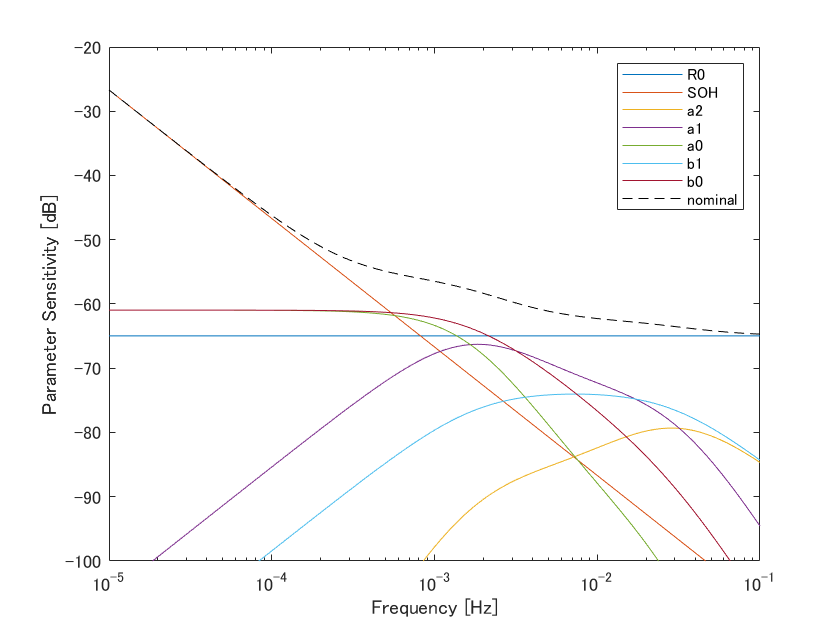

freq=logspace(-5,-1,100);
sensitibity_plot(Gr,freq,vars_r,varvals_r);
ylim([-100,-20])

### Cauer-type

n=3;
Zw= Cauer(n);
Gcau = (4.1-3.6)/(0.9-0.1)/(FCC0*SOH)/s+R0+Zw

$$Gcau = R_{0}+\frac{1}{\frac{1}{\frac{1}{\frac{1}{\frac{1}{C_{3}\,s+\frac{1}{R_{3}}}+\frac{1}{C_{2}\,s}}+\frac{1}{R_{2}}}+\frac{1}{C_{1}\,s}}+\frac{1}{R_{1}}}+\frac{5}{8\,{\mathrm{FCC}}_{0}\,\mathrm{SOH}\,s}$$

Gcau = subs(Gcau,FCC0,65.6*3600);

freq=logspace(-5,-1,100);
Rd_v= 0.896e-3;
taud_v = 224;
Cd_v = taud_v/Rd_v;
vars_cau    = {     R0,  SOH};
varvals_cau = {0.565e-3,  0.91};
for k=1:n
    vars_cau{end+1} = sym(sprintf('R%d',k));
    varvals_cau{end+1} = Rd_v/(4*k-3);
    vars_cau{end+1} = sym(sprintf('C%d',k));
    varvals_cau{end+1} = Cd_v/(4*k-1);
end

Display parmeter sensitivity

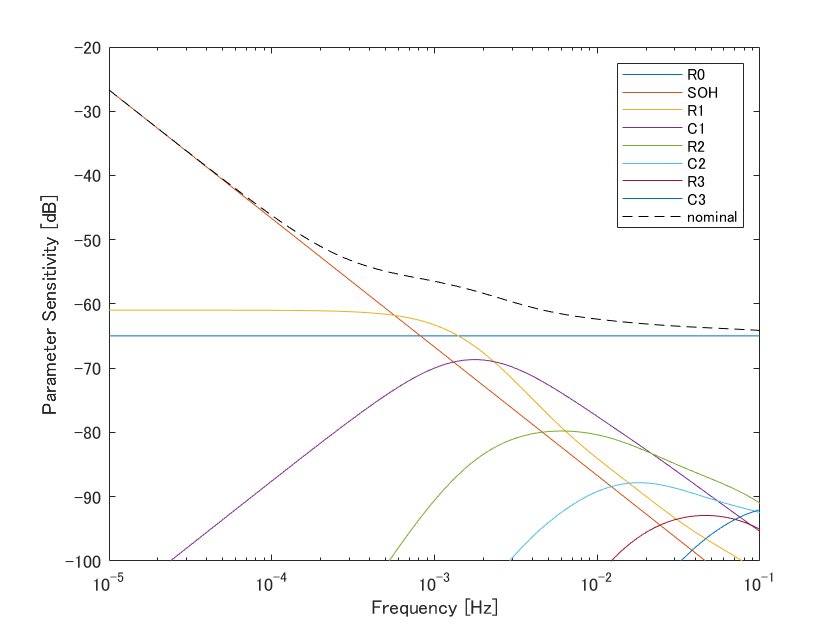

sensitibity_plot(Gcau,freq,vars_cau,varvals_cau);
ylim([-100,-20])

### Foster-type

n=3;
Gfos = (4.1-3.6)/(0.9-0.1)/(FCC0*SOH)/s+R0;
vars_fos    = {     R0,  SOH};
varvals_fos = {0.565e-3,  0.91};
Rd_v= 0.896e-3;
taud_v = 224;
Cd_v = taud_v/Rd_v;

for k=1:n
    Rk = sym(sprintf('R%d',k));
    Ck = sym(sprintf('C%d',k));
    Gfos = Gfos + Rk/(s*Rk*Ck+1);
    vars_fos{end+1} = Rk;
    varvals_fos{end+1} = 8*Rd_v/((2*k-1)^2*pi^2);
    vars_fos{end+1} = Ck;
    varvals_fos{end+1} = Cd_v/2;
end
Gfos

$$Gfos = R_{0}+\frac{R_{1}}{C_{1}\,R_{1}\,s+1}+\frac{R_{2}}{C_{2}\,R_{2}\,s+1}+\frac{R_{3}}{C_{3}\,R_{3}\,s+1}+\frac{5}{8\,{\mathrm{FCC}}_{0}\,\mathrm{SOH}\,s}$$

Display parameter sensitivity

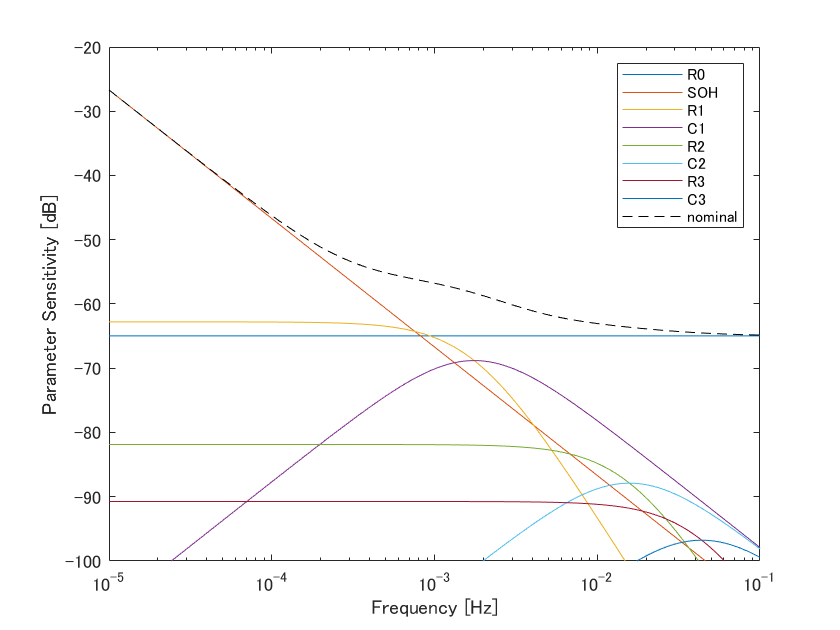

Gfos = subs(Gfos,FCC0,65.6*3600);
freq=logspace(-5,-1,100);
sensitibity_plot(Gfos,freq,vars_fos,varvals_fos);
ylim([-100,-20])

function [out] = tfmodel(m)
    s = sym('s');
    Rd = sym('R_d');
    taud = sym('tau_d');
    Z = @(n) Rd/(4*n-3);
    Y = @(n) taud*s/(Rd*(4*n-1));
    out = Zw_rec(Z,Y,1,m+1);
    function out = Zw_rec(Z,Y,k,m)
        if k==m
            out=0;
        else
            out = 1/(1/Z(k)+1/(1/Y(k)+Zw_rec(Z,Y,k+1,m)));
        end
    end
end

function [ret] = Cauer(n)
    function ret = Cauer_rec(n,m)
        if n==0
            ret = 0;
        else
            Rn = sym(sprintf('R%d',m-n+1));
            Cn = sym(sprintf('C%d',m-n+1));
            s = sym('s');
            ret = 1/(1/Rn+1/((1/s/Cn)+Cauer_rec(n-1,m)));
        end
    end
    ret = Cauer_rec(n,n);
end